## 자석 (Sami)

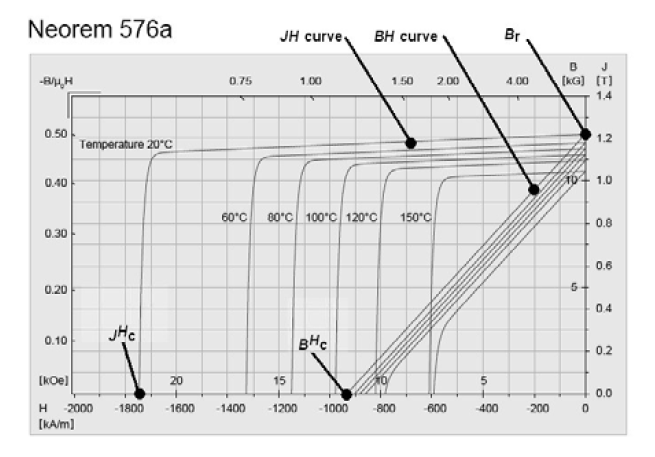

flux density through the magnet as a function of the magnetic field (BH curves)


$$$B_{\mathrm{m}}=\mu_0 H_{\mathrm{m}}+J_{\mathrm{m}}$.$$


magnetic polarization as a function of the magnetic field (JH curves).

$$\left({ }_J H_{\mathrm{c}}\right)$$ intrinsic coercivity (JH curve)

$$\left({ }_B H_{\mathrm{c}}\right)$$normal coercivity (BH curve)

Recoil permeability shows the slope of the BH curve.

Squareness defines the quality of the JH curve

좋은 자석은 세 번째 사분면에서 JH 곡선의 모서리가 사각형입니다.

good magnets have a square corner in their JH curve in the third quadrant

while poor magnets have a round corner.

## MotorCAD 

Magnet Properties - Help

솔리드 데이터베이스의 자석 머티리얼에 대한 자석 프로퍼티를 표시합니다. 선택한 머티리얼 유형이 물리적 탭을 통해 자석 설정으로 설정된 경우에만 컨트롤이 활성화됩니다.입력된 자석 속성을 사용하여 자석의 감자 곡선이 계산되며, 자석 데이터 시트와 비교하여 확인할 수 있습니다.비선형 감자 곡선은 감자 곡선 방법이 비선형으로 설정된 경우에만 FEA 솔버에서 사용되며, 그렇지 않은 경우 선형 모델이 사용됩니다.

선형 모델에 대한 설명은 이 페이지 하단을 참조하세요.

자기 특성은 온도에 따라 달라지므로 세 가지 관련 온도를 지정해야 합니다:

다음 입력값을 사용할 수 있으며, 자화 곡선 계산에 필요합니다:

온도의존성

Br과 HcJ의 온도 의존성은 관계를 통해 RTC α와 β에 인코딩됩니다:


$$$B r_{\text {Magnet temp }}=B r($ Tref $) \cdot\left(1+\frac{\alpha \cdot(\text { Magnet temp }- \text { Tref })}{100}\right)$$$



$$$H c J_{\text {Magnet temp }}=H c J($ Tref $) \cdot\left(1+\frac{\beta \cdot(\text { Magnet temp }- \text { Tref })}{100}\right)$$$


**가능한 옵션**

- 상대 투과성 입력(Direct Input): μᵣ 값을 알고 있는 경우 이 옵션을 사용합니다

- .Br 및 Hc에서 계산: μᵣ을 모르지만 일부 온도에 대해 완전히 선형인 자화 곡선(B-H)에 액세스할 수 있는 경우 이 옵션을 사용합니다(이 계산에서 온도는 중요하지 않음).

- - 두 지점에서 계산: μᵣ를 모르고 전체 곡선에 걸쳐 선형인 자화 곡선(B-H)이 없는 경우 이 옵션을 사용합니다.  이 옵션의 경우 B-H 곡선의 두 점의 B 및 H 값을 입력하며, 이 점들은 곡선의 선형 영역에 있습니다.

- Hc(Tref)에서 계산: μᵣ를 모르고 자화 곡선(B-H)이 기준 온도 Tref에서 완전히 선형인 경우 이 옵션을 사용합니다.

μᵣ 계산기에 입력한 H와 B의 모든 값은 양수여야 한다는 점에 유의하세요.

예를 들어, 온도 -40°C에서 자석 N30UH의 경우, B-H 곡선은 선형이며, Br(-40°C) = 1.205T, HcJ(-40°C) = 923000 A/m입니다. 이 값을 입력하면 μᵣ = 1.0389가 됩니다, 이 값은 자화 곡선을 계산하는 데 사용됩니다:

### 비선형 감자곡선 모델

모든 자석 데이터가 입력되면 비선형 모델 [1]을 사용하여 감자 곡선을 계산합니다.

[1] Sami Ruoho, *Modeling **Demagnetization** of  Sintered NdFeB Magnet Material in Time-Discretized Finite Element  Analysis*, Aalto University publication series DOCTORAL DISSERTATIONS,  1/2011, 2011, ISBN 978-952-60-4001-1.


$$$B=B r+\mu_0 \mu_r H-E \cdot e^{-k_1 \cdot\left(k_2+H\right)}$$$


k2 is a constant defined by


$$$k_2=-\frac{\ln \left[\left(B r+\left(\mu_r-1\right) \cdot \mu_0 \cdot H c J\right) \cdot \frac{1}{E}\right]}{k_1}-H c J$$$


모든 자석 데이터가 올바르게 입력되면 데이터 시트의 자화 곡선과 비교할 수 있도록 자화 곡선이 계산되고 표시됩니다.

곡선은 선택한 온도와 BPM 계산 탭에 지정된 자석 온도에 대해 그려집니다. 자화 곡선이 그려지는 온도를 변경하려면를 변경하려면 입력 데이터 -> 설정 -> 그래프 탭에서 변경할 수 있습니다(그래프 [BPM, SYNC, SRM] 참조):

#### MotorCAD Material DB(Mdb)파일을 JMAG용 Format으로 변환 (3)

N52UHmdbPath="Z:\01_Codes_Projects\git_fork_emach\tools\N52UH.mdb"
N45UHmdbPath="Z:\01_Codes_Projects\git_fork_emach\tools\ArnoldN45UH.mdb"

N52UH=readMCADMaterialDBFile(N52UHmdbPath)
TotalDataN52UH=devConvertMagnetData2CellFormat(N52UH)


### 비선형 감자곡선모델(fitting)

#### alpha Beta

TotalDataN52UH.str4DataTablePerTemp.DataAtTemp100
Table1=TotalDataN52UH.str4DataTablePerTemp.DataAtTemp140
Table2=TotalDataN52UH.str4DataTablePerTemp.DataAtTemp200
    [alpha(end+1), beta(end+1)] = computeMCADMagTempCoefficients(Table1,Table2)

fieldNames=fieldnames(TotalDataN52UH.str4DataTablePerTemp)
    
alpha=[]
beta=[]
for i=1:length(fieldNames)-1
    fieldName1=fieldNames{i};
    fieldName2=fieldNames{end-(i-1)};
    table1=TotalDataN52UH.str4DataTablePerTemp.(fieldName1)
    table2=TotalDataN52UH.str4DataTablePerTemp.(fieldName2)
    [alpha(end+1), beta(end+1)] = computeMCADMagTempCoefficients(table1,table2)
end




Using Non-linear Model

% Relative Permeability
% Direct Input
N42EH
MotorCADMagnetDirectInput=TotalDataN42EH.MagnetTable.AutomationName
save('MotorCADMagnetDirectInput','MotorCADMagnetDirectInput')


### [TC]Fitting

Temperaturemu_r={};
for i=1:length(fieldNames)
    fieldName=fieldNames{i};
    BHtable=TotalDataN52UH.str4DataTablePerTemp.(fieldName);
    fitresult = defNonlinearDemagnetizationModelBySami(BHtable);

    Hfit = linspace(min(BHtable.Hvalue), max(BHtable.Hvalue), 4000);
    Bfit = feval(fitresult, Hfit);
    
    %%
    Temp1str=BHtable.Properties.Description;
    Temperaturemu_r{end+1,1}=str2double(strrep(Temp1str,'Temp=',''));
    Temperaturemu_r{end,2} =fitresult.mu_r;
    % 플롯

    plot(BHtable.Hvalue, BHtable.Bvalue, 's', 'DisplayName', 'Validation Data');
    hold on;
    % plot(TotalTable.Hvalue, TotalTable.Bvalue, 'bo', 'DisplayName', 'Training Data');
    plot(Hfit, Bfit, 'k-', 'DisplayName', 'Fit Curve');
    ylim([-2,2])
end



k1 is sqaureness Factor

% k1 = 9.66E-5; % 주어진 값~ 


k2 is a constant defined 


$$$k_2=-\frac{\ln \left[\left(B r+\left(\mu_r-1\right) \cdot \mu_0 \cdot H c J\right) \cdot \frac{1}{E}\right]}{k_1}-H c J$$$


모든 자석 데이터를 올바르게 입력하면 자화 곡선이 계산되어 표시되므로 데이터 시트의 자화 곡선과 비교할 수 있습니다.

곡선은 선택한 온도와 BPM 계산 탭에 지정된 자석 온도에 대해 그려집니다. 자화 곡선이 그려지는 온도를 변경하려는 경우

자화 곡선이 그려지는 온도를 변경하려면 입력 데이터-> 설정-> 그래프 탭에서 변경할 수 있습니다(그래프 [BPM, SYNC, SRM] 참조):

계산된 자화 곡선은 자석 데이터 시트에 제공된 자화 곡선과 비교할 수 있으며, 더 가까운 일치를 원할 경우 입력 파라미터를 수정할 수 있습니다.

특히 기본적으로 재료에는 [1]에서 제안한 대로 6E-5의 제곱 계수가 주어지지만, 이 값을 수정하여 니 포인트의 선명도에 영향을 줄 수 있습니다. 예를 들어

자석 N30UH의 경우 제각률 계수를 6E-5(왼쪽) 또는 3E-5(오른쪽)로 선택하면 다음과 같이 비교됩니다:

#### Knee Point Detection

deviation from 10% Gradient of Demagnetization Curve  


$$$B=B r+\mu_0 \mu_r H-E \cdot e^{-k_1 \cdot\left(k_2+H\right)}$$$


## Jmag

Emdyne Code

### Nonlinear 

#### (Irreversible/Thermal  demagnetization/Demagnetizing field) 

자기장에 대해 비선형적인 특성을 보이는 자석으로, 온도와 해당 온도에서 BH 곡선(자화 곡선)의 대략적인 직선을 정의하는 표를 가지고 있습니다.

각 온도에 대한 B-H 곡선의 대략적인 직선을 정의합니다.

다

(Coercitivity Force], 

[잔류 자속 밀도], 

relative permeability

[처짐 상대 투과성]).

#### 3 - 1. (Bilinear Approximation)]

#### 8 - 2 Point Array)]

- **[B-H Curve (temperature dependent)] (magnetic  field-magnetic flux tables at any temperatures)**

- iHc의 점을 통과하는 온도에 따른 B-H 곡선을 지정합니다.

- 온도에 따라 달라지는 BH 곡선은 선형적으로 보간됩니다(온도 축과 자기장 축 모두).

-계산 중에 정의되지 않은 온도를 참조하는 경우 해당 온도에 가까운 값에서 B-H 곡선을 사용하여 선형 보간을 통해 얻은 값이 사용됩니다.

-각 BH 커브로 정의된 범위를 벗어나는 범위는 테이블의 마지막 gradient으로 외삽됩니다. 이 유형의 자석에는 [외삽 방법]을 선택할 수 없습니다.

-동일한 온도에서 데이터를 보유하기 위해 온도에 따라 달라지는 BH 곡선과 온도 리코일 테이블이 필요하지 않습니다. 예를 들어 다음 설정은 문제 없이 구성할 수 있습니다:

        [B-H 곡선(온도에 따라 다름)] 0deg C, 20deg C, 40deg C에서 BH 곡선을 정의합니다.

        온도 리코일 테이블은 10deg C, 30deg C, 50deg C의 데이터 포인트를 정의합니다.

**[Temperature Recoil Table] (slope of recoil line at any  temperature)**

- 온도를 오름차순으로 입력합니다.

- 상대 투과성에 대해 0보다 작은 값은 설정하지 마십시오.

- 온도 리코일 테이블은 선형 보간됩니다.

- 분석 중에 자석 온도가 온도 recoil 표로 정의된 온도 범위를 초과하지 않도록 합니다. 자석 온도가 표로 정의된 온도 범위를 초과하면 표의 끝점 값(최고 온도 또는 최저 온도에서의 상대 투과성)이 계산에 사용됩니다.

- 가변 자석 사용]을 선택 취소한 상태에서 한 번의 자화 후 자화가 발생하면 해당 시간 동안의 자석 온도에서의 상대 투자율은 온도 리코일 테이블을 기반으로 계산됩니다. 작동 지점은 해당 상대 투자율 기울기가 있는 선에서 결정됩니다. 가변 자석 사용]을 선택하면 온도 리코일 테이블은 분석에 사용되지 않습니다.

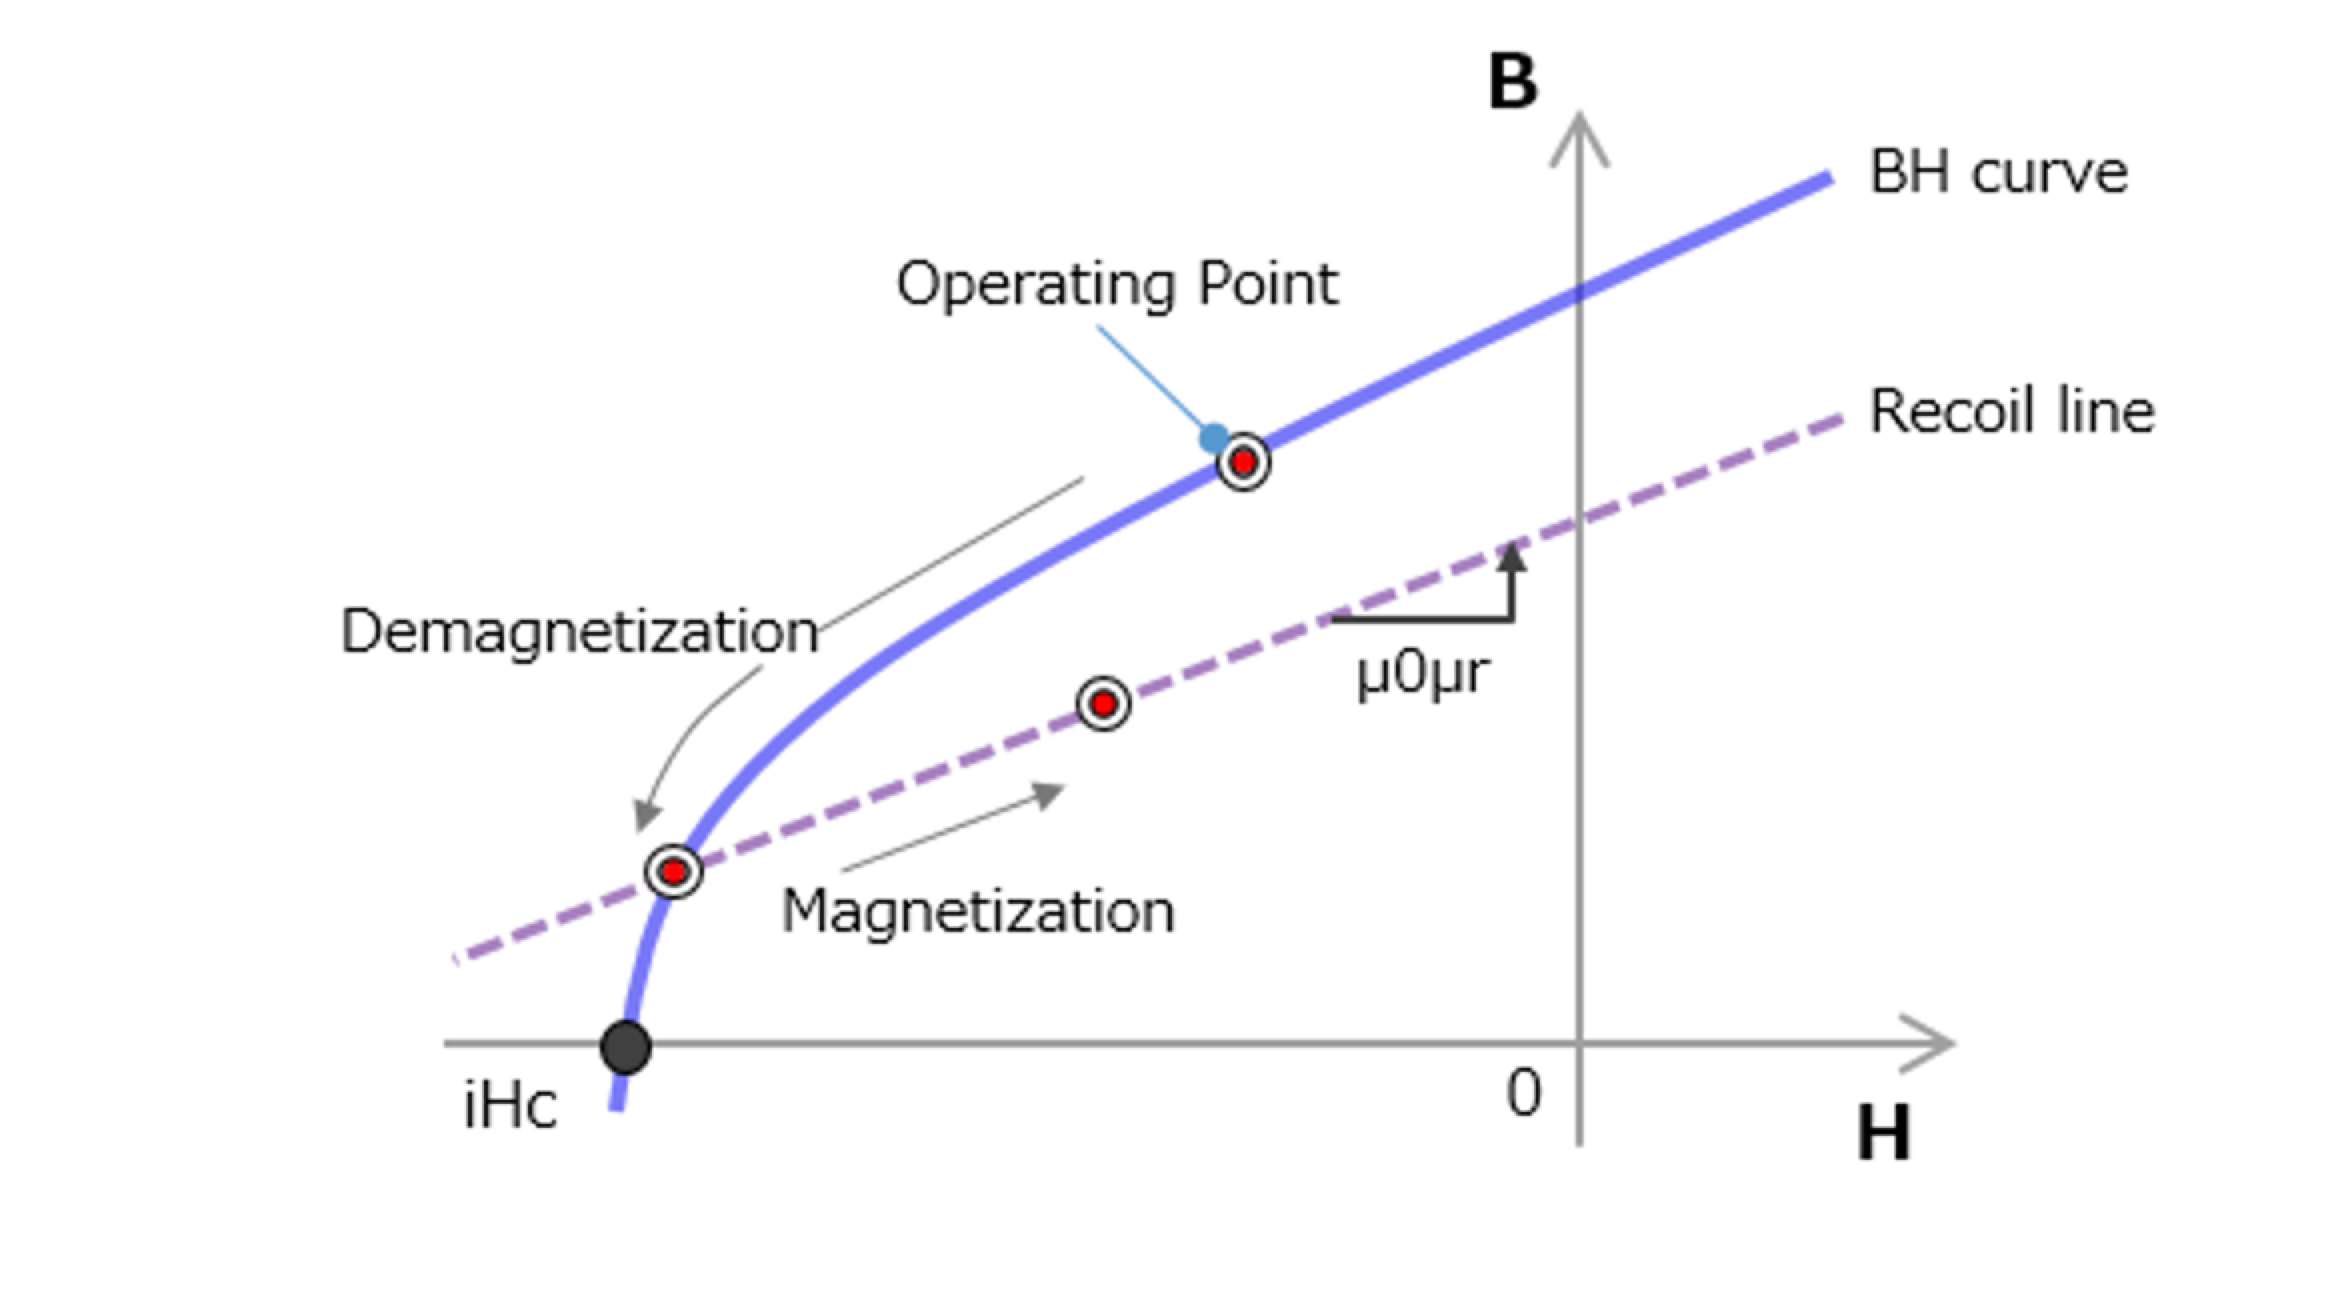

% Material Library 가져오기
materialLib = app.GetMaterialLibrary();
% 사용자 재료 가져오기
userMaterial = materialLib.GetUserMaterial('BJMT_N52UH');

% TemperatureBhTable 설정
fieldNames=fieldnames(TotalDataN52UH.DataCellStrPerTemp)
for dataIndex=1:length(fieldNames)
    fieldName=fieldNames{dataIndex};
    temperature =str2double(strrep(fieldName,"DataAtTemp","")) ; % 온도 설정
    refarray=TotalDataN52UH.DataCellStrPerTemp.(fieldName)
    app.GetMaterialLibrary().GetUserMaterial("BJMT_N52UH").SetTableList("TemperatureBhTable", temperature, "deg C", refarray)
end

% RecoilPermeabilityTable 설정
recoilPermeabilityTable = userMaterial.GetTable('RecoilPermeabilityTable');
recoilPermeabilityTable.SetName('N52UH');
recoilPermeabilityTable.SetTable(Temperaturemu_r);

#### (Irreversible/Demagnetizing  field)]

### Linear 

#### (Relative permeability-Coercive force bHc)], 

#### (Relative  permeability-Residual flux density)] 

#### (Coercive force bHc-Residual flux  density)]